# Plot numerical convergence of contributive case, infinite horizon version

*Clean workspace, layout settings:*

clear;
clc;
close all;
base.layout();

This workbook solves the model for the Argentina infinite horizon case with various values of $\epsilon$, to show the convergence of policies as it tends to the analytical case of $\epsilon=0$ (universal).

## 1. Settings

Load calibration from the Argentina case:

load('ArgentinaParameters.mat','out');
load('ArgentinaParametersIH.mat','IH_par');
load('ArgentinaTargets.mat','target');

For the infinite horizon version, given parameter values, we start by pre-approximating a labor equilibrium function. The settings for this approximation:

- approx.n: Number of gridpoints for $\tau_t$ in approximation of labor function.

- approx.nn: Number of gridpoints for $\tau_{t+1}$ in approximation of labor function.

- approx.s, approx.ss: Shape parameters used in nonlinear grid functions.

approx = struct('n',250,'nn',250,'s',0.7,'ss',1.2);
hfuncIH = IH.h_EE_approximation(IH_par,approx);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

Define numerical settings (add length of nu grid later):

- np.tol_diff: Maximum difference between two iterations when identifying a fixed point.

- np.tol_solver: Maximum tolerance for numerical solvers.

- np.max_iter: Upper bound on number of iterations applied in various algorithms.

- np.n_h: Number of gridpoints in the grid of $h$

- np:n_test: Size of grid of taxes to test if the algorithm has converged.

np = struct('tol_diff',1e-5,...
            'tol_solver',1e-7,...
            'max_iter',50,...
            'n_h',150,...
            'n_test',100,...
            'n_nu', 1);

Define grids to be used:

grids = struct('h', linspace(hfuncIH(1,0), hfuncIH(0,1),np.n_h),...
               'test',linspace(0.01, 0.99, np.n_test),...
               'nu', out.par.nu_v(end),...
               'eps', [0, 0.25, 0.5, 1]);

For each level of epsilon, solve the model and store solution:

sols = cell(length(grids.eps),1);
taxes = cell(1,length(grids.eps));
pars = cell(length(grids.eps),1);
for i=1:length(grids.eps)
    s = struct();
    pars{i} = IH_par;
    pars{i}.epsilon = grids.eps(i);
    [s.sample, s.dif, s.maxdiff, s.iter, s.tau_cell, s.tau_m_cell, s.h] = IH.GradientFree_Policy(pars{i}, np, grids, hfuncIH, nan);
    sols{i} = s;
end

Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.


% Solve given terminal policy:
for i=1:length(grids.eps)
    [s,p] = IH.identifyPolicy(pars{i}, np, grids, hfuncIH,nan);
    sols{i}.sim = SolveF.sim_c_unique(p,s);
    taxes{i} = sols{i}.sim.tau;
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

Print the convergence of policies:

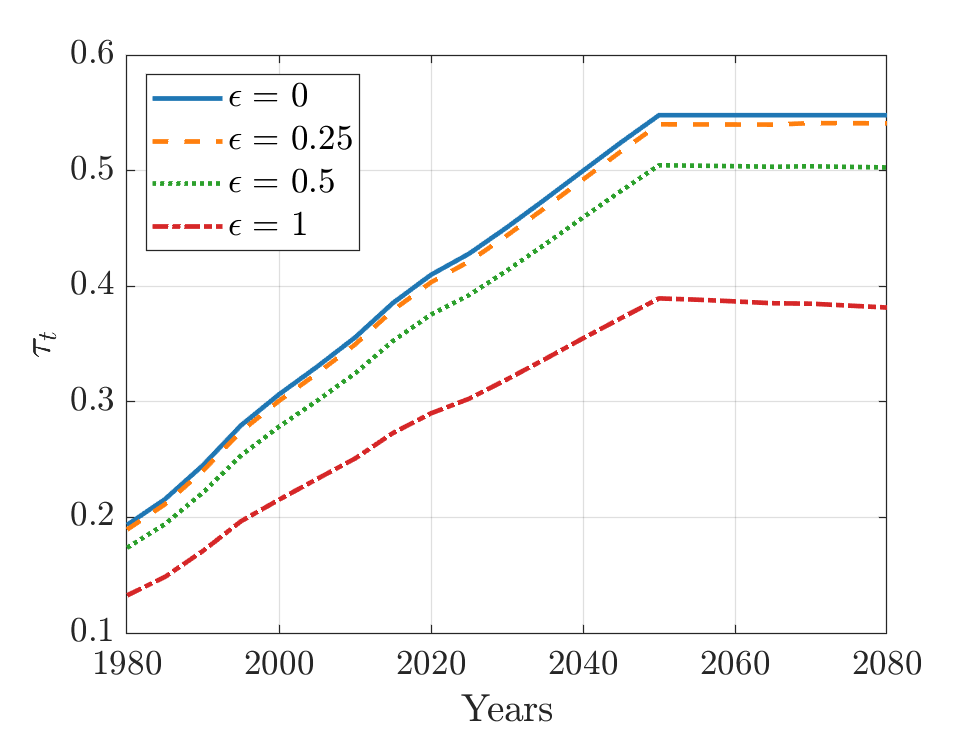

psettings = figs.def_psettings(struct('LabelFontSize',15));
print = 1; % If 1 print to pdf, if 0 don't.
prefix = 'convergenceTD';
sims = cell2mat(taxes);
figs.comparetaxes_Convergence(IH_par.dates,psettings,sims,grids,print,prefix);